clc, clear

l = 101;
step = 0.1;
T = (l - 1)*step;
delta = zeros(3, l);
theta = zeros(3, l);
th_IKP = zeros(3, l);
[t1, t2, t3] = deal(zeros(2,l), zeros(2,l), zeros(2,l));
i = 0;

for t=0:step:T
    disp('-------------------------------')
    i = i+1
    theta(1, i) = pi/4 + pi/9*sin(pi/5*t);
    theta(2, i) = pi/6 + pi/18*sin(pi/10*t);
    theta(3, i) = -pi/9 - pi/36*sin(pi/15*t);
    [thetaIKP_1, thetaIKP_2, thetaIKP_3] = IKP(theta(1, i), theta(2, i), theta(3, i));
    
    d11 = abs((theta(1, i) - thetaIKP_1(1))/theta(1, i)) *100;
    d12 = abs((theta(1, i) - thetaIKP_1(2))/theta(1, i)) *100;
    d21 = abs((theta(2, i) - thetaIKP_2(1))/theta(2, i)) *100;
    d22 = abs((theta(2, i) - thetaIKP_2(2))/theta(2, i)) *100;
    d31 = abs((theta(3, i) - thetaIKP_3(1))/theta(3, i)) *100;
    d32 = abs((theta(3, i) - thetaIKP_3(2))/theta(3, i)) *100;
    
    if d11<=d12
        th_IKP(1, i) = thetaIKP_1(1);
    else
        th_IKP(1, i) = thetaIKP_1(2);
    end
    
    if d21<=d22
        th_IKP(2, i) = thetaIKP_2(1);
    else
        th_IKP(2, i) = thetaIKP_2(2);
    end
    
    if d31<=d32
        th_IKP(3, i) = thetaIKP_3(1);
    else
        th_IKP(3, i) = thetaIKP_3(2);
    end
    
    delta(1, i) = min(d11, d12);
    delta(2, i) = min(d21, d22);
    delta(3, i) = min(d31, d32);
    
    t1(1, i) = thetaIKP_1(1);
    t1(2, i) = thetaIKP_1(2);
    t2(1, i) = thetaIKP_2(1);
    t2(2, i) = thetaIKP_2(2);
    t3(1, i) = thetaIKP_3(1);
    t3(2, i) = thetaIKP_3(2);
   
end

-------------------------------


i = 1

$$th1\_1 = 1.338767$$

$$th1\_2 = 0.7853982$$

$$th2\_1 = -0.5235988$$

$$th2\_2 = 0.5235988$$

$$th3\_1 = 0.144763$$

$$th3\_2 = -0.3490659$$

-------------------------------


i = 2

$$th1\_1 = 0.8073162$$

$$th1\_2 = 1.366494$$

$$th2\_1 = 0.529081$$

$$th2\_2 = -0.529081$$

$$th3\_1 = -0.3508934$$

$$th3\_2 = 0.148091$$

-------------------------------


i = 3

$$th1\_1 = 1.394129$$

$$th1\_2 = 0.8291477$$

$$th2\_1 = -0.5345578$$

$$th2\_2 = 0.5345578$$

$$th3\_1 = 0.1514143$$

$$th3\_2 = -0.3527202$$

-------------------------------


i = 4

$$th1\_1 = 0.8508066$$

$$th1\_2 = 1.42158$$

$$th2\_1 = 0.5400238$$

$$th2\_2 = -0.5400238$$

$$th3\_1 = -0.3545454$$

$$th3\_2 = 0.1547285$$

-------------------------------


i = 5

$$th1\_1 = 0.8722073$$

$$th1\_2 = 1.448757$$

$$th2\_1 = 0.5454736$$

$$th2\_2 = -0.5454736$$

$$th3\_1 = -0.3563681$$

$$th3\_2 = 0.1580294$$

-------------------------------


i = 6

$$th1\_1 = 0.8932654$$

$$th1\_2 = 1.475569$$

$$th2\_1 = 0.5509017$$

$$th2\_2 = -0.5509017$$

$$th3\_1 = -0.3581877$$

$$th3\_2 = 0.1613127$$

-------------------------------


i = 7

$$th1\_1 = 0.9138979$$

$$th1\_2 = 1.501926$$

$$th2\_1 = 0.556303$$

$$th2\_2 = -0.556303$$

$$th3\_1 = -0.3600032$$

$$th3\_2 = 0.1645742$$

-------------------------------


i = 8

$$th1\_1 = 1.527743$$

$$th1\_2 = 0.9340232$$

$$th2\_1 = -0.561672$$

$$th2\_2 = 0.561672$$

$$th3\_1 = 0.1678096$$

$$th3\_2 = -0.361814$$

-------------------------------


i = 9

$$th1\_1 = 0.9535619$$

$$th1\_2 = 1.552935$$

$$th2\_1 = 0.5670033$$

$$th2\_2 = -0.5670033$$

$$th3\_1 = -0.3636192$$

$$th3\_2 = 0.1710149$$

-------------------------------


i = 10

$$th1\_1 = 0.972437$$

$$th1\_2 = 1.577417$$

$$th2\_1 = 0.5722919$$

$$th2\_2 = -0.5722919$$

$$th3\_1 = -0.365418$$

$$th3\_2 = 0.1741857$$

-------------------------------


i = 11

$$th1\_1 = 0.9905739$$

$$th1\_2 = 1.601111$$

$$th2\_1 = 0.5775324$$

$$th2\_2 = -0.5775324$$

$$th3\_1 = -0.3672096$$

$$th3\_2 = 0.1773181$$

-------------------------------


i = 12

$$th1\_1 = 1.007901$$

$$th1\_2 = 1.623939$$

$$th2\_1 = 0.5827197$$

$$th2\_2 = -0.5827197$$

$$th3\_1 = -0.3689932$$

$$th3\_2 = 0.180408$$

-------------------------------


i = 13

$$th1\_1 = 1.02435$$

$$th1\_2 = 1.645828$$

$$th2\_1 = 0.5878486$$

$$th2\_2 = -0.5878486$$

$$th3\_1 = -0.3707681$$

$$th3\_2 = 0.1834513$$

-------------------------------


i = 14

$$th1\_1 = 1.039856$$

$$th1\_2 = 1.666707$$

$$th2\_1 = 0.5929142$$

$$th2\_2 = -0.5929142$$

$$th3\_1 = -0.3725335$$

$$th3\_2 = 0.186444$$

-------------------------------


i = 15

$$th1\_1 = 1.054358$$

$$th1\_2 = 1.68651$$

$$th2\_1 = 0.5979113$$

$$th2\_2 = -0.5979113$$

$$th3\_1 = -0.3742886$$

$$th3\_2 = 0.1893824$$

-------------------------------


i = 16

$$th1\_1 = 1.067798$$

$$th1\_2 = 1.705173$$

$$th2\_1 = 0.6028351$$

$$th2\_2 = -0.6028351$$

$$th3\_1 = -0.3760327$$

$$th3\_2 = 0.1922625$$

-------------------------------


i = 17

$$th1\_1 = 1.080124$$

$$th1\_2 = 1.72264$$

$$th2\_1 = 0.6076807$$

$$th2\_2 = -0.6076807$$

$$th3\_1 = -0.3777649$$

$$th3\_2 = 0.1950805$$

-------------------------------


i = 18

$$th1\_1 = 1.091287$$

$$th1\_2 = 1.738856$$

$$th2\_1 = 0.6124433$$

$$th2\_2 = -0.6124433$$

$$th3\_1 = -0.3794845$$

$$th3\_2 = 0.1978328$$

-------------------------------


i = 19

$$th1\_1 = 1.101242$$

$$th1\_2 = 1.753772$$

$$th2\_1 = 0.6171182$$

$$th2\_2 = -0.6171182$$

$$th3\_1 = -0.3811908$$

$$th3\_2 = 0.2005156$$

-------------------------------


i = 20

$$th1\_1 = 1.109951$$

$$th1\_2 = 1.767345$$

$$th2\_1 = 0.6217008$$

$$th2\_2 = -0.6217008$$

$$th3\_1 = -0.382883$$

$$th3\_2 = 0.2031255$$

-------------------------------


i = 21

$$th1\_1 = 1.779534$$

$$th1\_2 = 1.11738$$

$$th2\_1 = -0.6261867$$

$$th2\_2 = 0.6261867$$

$$th3\_1 = 0.2056589$$

$$th3\_2 = -0.3845603$$

-------------------------------


i = 22

$$th1\_1 = 1.790305$$

$$th1\_2 = 1.123497$$

$$th2\_1 = -0.6305712$$

$$th2\_2 = 0.6305712$$

$$th3\_1 = 0.2081125$$

$$th3\_2 = -0.3862221$$

-------------------------------


i = 23

$$th1\_1 = 1.799631$$

$$th1\_2 = 1.128281$$

$$th2\_1 = -0.6348502$$

$$th2\_2 = 0.6348502$$

$$th3\_1 = 0.2104829$$

$$th3\_2 = -0.3878676$$

-------------------------------


i = 24

$$th1\_1 = 1.807487$$

$$th1\_2 = 1.131712$$

$$th2\_1 = -0.6390195$$

$$th2\_2 = 0.6390195$$

$$th3\_1 = 0.212767$$

$$th3\_2 = -0.3894961$$

-------------------------------


i = 25

$$th1\_1 = 1.813856$$

$$th1\_2 = 1.133775$$

$$th2\_1 = -0.6430748$$

$$th2\_2 = 0.6430748$$

$$th3\_1 = 0.2149615$$

$$th3\_2 = -0.3911068$$

-------------------------------


i = 26

$$th1\_1 = 1.818726$$

$$th1\_2 = 1.134464$$

$$th2\_1 = -0.6470122$$

$$th2\_2 = 0.6470122$$

$$th3\_1 = 0.2170635$$

$$th3\_2 = -0.3926991$$

-------------------------------


i = 27

$$th1\_1 = 1.822088$$

$$th1\_2 = 1.133775$$

$$th2\_1 = -0.6508278$$

$$th2\_2 = 0.6508278$$

$$th3\_1 = 0.2190701$$

$$th3\_2 = -0.3942722$$

-------------------------------


i = 28

$$th1\_1 = 1.823943$$

$$th1\_2 = 1.131712$$

$$th2\_1 = -0.6545179$$

$$th2\_2 = 0.6545179$$

$$th3\_1 = 0.2209784$$

$$th3\_2 = -0.3958256$$

-------------------------------


i = 29

$$th1\_1 = 1.824294$$

$$th1\_2 = 1.128281$$

$$th2\_1 = -0.6580787$$

$$th2\_2 = 0.6580787$$

$$th3\_1 = 0.2227858$$

$$th3\_2 = -0.3973584$$

-------------------------------


i = 30

$$th1\_1 = 1.823152$$

$$th1\_2 = 1.123497$$

$$th2\_1 = -0.6615068$$

$$th2\_2 = 0.6615068$$

$$th3\_1 = 0.2244896$$

$$th3\_2 = -0.39887$$

-------------------------------


i = 31

$$th1\_1 = 1.82053$$

$$th1\_2 = 1.11738$$

$$th2\_1 = -0.6647989$$

$$th2\_2 = 0.6647989$$

$$th3\_1 = 0.2260873$$

$$th3\_2 = -0.4003598$$

-------------------------------


i = 32

$$th1\_1 = 1.816451$$

$$th1\_2 = 1.109951$$

$$th2\_1 = -0.6679516$$

$$th2\_2 = 0.6679516$$

$$th3\_1 = 0.2275767$$

$$th3\_2 = -0.4018271$$

-------------------------------


i = 33

$$th1\_1 = 1.101242$$

$$th1\_2 = 1.810939$$

$$th2\_1 = 0.6709618$$

$$th2\_2 = -0.6709618$$

$$th3\_1 = -0.4032712$$

$$th3\_2 = 0.2289554$$

-------------------------------


i = 34

$$th1\_1 = 1.804027$$

$$th1\_2 = 1.091287$$

$$th2\_1 = -0.6738266$$

$$th2\_2 = 0.6738266$$

$$th3\_1 = 0.2302213$$

$$th3\_2 = -0.4046916$$

-------------------------------


i = 35

$$th1\_1 = 1.795751$$

$$th1\_2 = 1.080124$$

$$th2\_1 = -0.6765431$$

$$th2\_2 = 0.6765431$$

$$th3\_1 = 0.2313724$$

$$th3\_2 = -0.4060876$$

-------------------------------


i = 36

$$th1\_1 = 1.78615$$

$$th1\_2 = 1.067798$$

$$th2\_1 = -0.6791088$$

$$th2\_2 = 0.6791088$$

$$th3\_1 = 0.2324069$$

$$th3\_2 = -0.4074585$$

-------------------------------


i = 37

$$th1\_1 = 1.054358$$

$$th1\_2 = 1.775273$$

$$th2\_1 = 0.6815209$$

$$th2\_2 = -0.6815209$$

$$th3\_1 = -0.4088039$$

$$th3\_2 = 0.2333229$$

-------------------------------


i = 38

$$th1\_1 = 1.763169$$

$$th1\_2 = 1.039856$$

$$th2\_1 = -0.6837772$$

$$th2\_2 = 0.6837772$$

$$th3\_1 = 0.234119$$

$$th3\_2 = -0.410123$$

-------------------------------


i = 39

$$th1\_1 = 1.02435$$

$$th1\_2 = 1.749892$$

$$th2\_1 = 0.6858754$$

$$th2\_2 = -0.6858754$$

$$th3\_1 = -0.4114154$$

$$th3\_2 = 0.2347935$$

-------------------------------


i = 40

$$th1\_1 = 1.007901$$

$$th1\_2 = 1.735502$$

$$th2\_1 = 0.6878134$$

$$th2\_2 = -0.6878134$$

$$th3\_1 = -0.4126804$$

$$th3\_2 = 0.2353452$$

-------------------------------


i = 41

$$th1\_1 = 0.9905739$$

$$th1\_2 = 1.720063$$

$$th2\_1 = 0.6895895$$

$$th2\_2 = -0.6895895$$

$$th3\_1 = -0.4139175$$

$$th3\_2 = 0.2357727$$

-------------------------------


i = 42

$$th1\_1 = 0.972437$$

$$th1\_2 = 1.703639$$

$$th2\_1 = 0.6912016$$

$$th2\_2 = -0.6912016$$

$$th3\_1 = -0.4151261$$

$$th3\_2 = 0.2360752$$

-------------------------------


i = 43

$$th1\_1 = 0.9535619$$

$$th1\_2 = 1.686301$$

$$th2\_1 = 0.6926484$$

$$th2\_2 = -0.6926484$$

$$th3\_1 = -0.4163058$$

$$th3\_2 = 0.2362515$$

-------------------------------


i = 44

$$th1\_1 = 0.9340232$$

$$th1\_2 = 1.668123$$

$$th2\_1 = 0.6939284$$

$$th2\_2 = -0.6939284$$

$$th3\_1 = -0.417456$$

$$th3\_2 = 0.2363009$$

-------------------------------


i = 45

$$th1\_1 = 0.9138979$$

$$th1\_2 = 1.649179$$

$$th2\_1 = 0.6950402$$

$$th2\_2 = -0.6950402$$

$$th3\_1 = -0.4185762$$

$$th3\_2 = 0.2362227$$

-------------------------------


i = 46

$$th1\_1 = 0.8932654$$

$$th1\_2 = 1.629549$$

$$th2\_1 = 0.6959829$$

$$th2\_2 = -0.6959829$$

$$th3\_1 = -0.4196659$$

$$th3\_2 = 0.2360165$$

-------------------------------


i = 47

$$th1\_1 = 0.8722073$$

$$th1\_2 = 1.609312$$

$$th2\_1 = 0.6967555$$

$$th2\_2 = -0.6967555$$

$$th3\_1 = -0.4207246$$

$$th3\_2 = 0.2356817$$

-------------------------------


i = 48

$$th1\_1 = 0.8508066$$

$$th1\_2 = 1.588551$$

$$th2\_1 = 0.6973571$$

$$th2\_2 = -0.6973571$$

$$th3\_1 = -0.4217519$$

$$th3\_2 = 0.2352183$$

-------------------------------


i = 49

$$th1\_1 = 1.567349$$

$$th1\_2 = 0.8291477$$

$$th2\_1 = -0.6977873$$

$$th2\_2 = 0.6977873$$

$$th3\_1 = 0.234626$$

$$th3\_2 = -0.4227474$$

-------------------------------


i = 50

$$th1\_1 = 1.545792$$

$$th1\_2 = 0.8073162$$

$$th2\_1 = -0.6980456$$

$$th2\_2 = 0.6980456$$

$$th3\_1 = 0.2339049$$

$$th3\_2 = -0.4237105$$

-------------------------------


i = 51

$$th1\_1 = 0.7853982$$

$$th1\_2 = 1.523965$$

$$th2\_1 = 0.6981317$$

$$th2\_2 = -0.6981317$$

$$th3\_1 = -0.4246408$$

$$th3\_2 = 0.2330553$$

-------------------------------


i = 52

$$th1\_1 = 1.501956$$

$$th1\_2 = 0.7634801$$

$$th2\_1 = -0.6980456$$

$$th2\_2 = 0.6980456$$

$$th3\_1 = 0.2320773$$

$$th3\_2 = -0.425538$$

-------------------------------


i = 53

$$th1\_1 = 1.47985$$

$$th1\_2 = 0.7416486$$

$$th2\_1 = -0.6977873$$

$$th2\_2 = 0.6977873$$

$$th3\_1 = 0.2309716$$

$$th3\_2 = -0.4264017$$

-------------------------------


i = 54

$$th1\_1 = 0.7199897$$

$$th1\_2 = 1.457734$$

$$th2\_1 = 0.6973571$$

$$th2\_2 = -0.6973571$$

$$th3\_1 = -0.4272314$$

$$th3\_2 = 0.2297387$$

-------------------------------


i = 55

$$th1\_1 = 0.698589$$

$$th1\_2 = 1.435694$$

$$th2\_1 = 0.6967555$$

$$th2\_2 = -0.6967555$$

$$th3\_1 = -0.4280269$$

$$th3\_2 = 0.2283795$$

-------------------------------


i = 56

$$th1\_1 = 1.413814$$

$$th1\_2 = 0.6775309$$

$$th2\_1 = -0.6959829$$

$$th2\_2 = 0.6959829$$

$$th3\_1 = 0.2268946$$

$$th3\_2 = -0.4287877$$

-------------------------------


i = 57

$$th1\_1 = 0.6568985$$

$$th1\_2 = 1.39218$$

$$th2\_1 = 0.6950402$$

$$th2\_2 = -0.6950402$$

$$th3\_1 = -0.4295136$$

$$th3\_2 = 0.2252853$$

-------------------------------


i = 58

$$th1\_1 = 0.6367732$$

$$th1\_2 = 1.370873$$

$$th2\_1 = 0.6939284$$

$$th2\_2 = -0.6939284$$

$$th3\_1 = -0.4302042$$

$$th3\_2 = 0.2235527$$

-------------------------------


i = 59

$$th1\_1 = 0.6172344$$

$$th1\_2 = 1.349974$$

$$th2\_1 = 0.6926484$$

$$th2\_2 = -0.6926484$$

$$th3\_1 = -0.4308591$$

$$th3\_2 = 0.2216982$$

-------------------------------


i = 60

$$th1\_1 = 1.329561$$

$$th1\_2 = 0.5983593$$

$$th2\_1 = -0.6912016$$

$$th2\_2 = 0.6912016$$

$$th3\_1 = 0.2197231$$

$$th3\_2 = -0.4314782$$

-------------------------------


i = 61

$$th1\_1 = 0.5802224$$

$$th1\_2 = 1.309711$$

$$th2\_1 = 0.6895895$$

$$th2\_2 = -0.6895895$$

$$th3\_1 = -0.4320612$$

$$th3\_2 = 0.217629$$

-------------------------------


i = 62

$$th1\_1 = 0.5628952$$

$$th1\_2 = 1.290497$$

$$th2\_1 = 0.6878134$$

$$th2\_2 = -0.6878134$$

$$th3\_1 = -0.4326077$$

$$th3\_2 = 0.2154178$$

-------------------------------


i = 63

$$th1\_1 = 0.5464461$$

$$th1\_2 = 1.271988$$

$$th2\_1 = 0.6858754$$

$$th2\_2 = -0.6858754$$

$$th3\_1 = -0.4331176$$

$$th3\_2 = 0.2130912$$

-------------------------------


i = 64

$$th1\_1 = 0.5309401$$

$$th1\_2 = 1.254252$$

$$th2\_1 = 0.6837772$$

$$th2\_2 = -0.6837772$$

$$th3\_1 = -0.4335907$$

$$th3\_2 = 0.2106513$$

-------------------------------


i = 65

$$th1\_1 = 0.5164383$$

$$th1\_2 = 1.237353$$

$$th2\_1 = 0.6815209$$

$$th2\_2 = -0.6815209$$

$$th3\_1 = -0.4340266$$

$$th3\_2 = 0.2081002$$

-------------------------------


i = 66

$$th1\_1 = 0.502998$$

$$th1\_2 = 1.22135$$

$$th2\_1 = 0.6791088$$

$$th2\_2 = -0.6791088$$

$$th3\_1 = -0.4344253$$

$$th3\_2 = 0.2054401$$

-------------------------------


i = 67

$$th1\_1 = 0.4906721$$

$$th1\_2 = 1.206298$$

$$th2\_1 = 0.6765431$$

$$th2\_2 = -0.6765431$$

$$th3\_1 = -0.4347866$$

$$th3\_2 = 0.2026734$$

-------------------------------


i = 68

$$th1\_1 = 0.4795094$$

$$th1\_2 = 1.19225$$

$$th2\_1 = 0.6738266$$

$$th2\_2 = -0.6738266$$

$$th3\_1 = -0.4351102$$

$$th3\_2 = 0.1998026$$

-------------------------------


i = 69

$$th1\_1 = 0.4695539$$

$$th1\_2 = 1.179251$$

$$th2\_1 = 0.6709618$$

$$th2\_2 = -0.6709618$$

$$th3\_1 = -0.4353961$$

$$th3\_2 = 0.1968305$$

-------------------------------


i = 70

$$th1\_1 = 0.4608449$$

$$th1\_2 = 1.167344$$

$$th2\_1 = 0.6679516$$

$$th2\_2 = -0.6679516$$

$$th3\_1 = -0.4356442$$

$$th3\_2 = 0.1937596$$

-------------------------------


i = 71

$$th1\_1 = 0.4534168$$

$$th1\_2 = 1.156567$$

$$th2\_1 = 0.6647989$$

$$th2\_2 = -0.6647989$$

$$th3\_1 = -0.4358543$$

$$th3\_2 = 0.1905929$$

-------------------------------


i = 72

$$th1\_1 = 1.146953$$

$$th1\_2 = 0.4472989$$

$$th2\_1 = -0.6615068$$

$$th2\_2 = 0.6615068$$

$$th3\_1 = 0.1873333$$

$$th3\_2 = -0.4360263$$

-------------------------------


i = 73

$$th1\_1 = 1.138528$$

$$th1\_2 = 0.4425152$$

$$th2\_1 = -0.6580787$$

$$th2\_2 = 0.6580787$$

$$th3\_1 = 0.183984$$

$$th3\_2 = -0.4361601$$

-------------------------------


i = 74

$$th1\_1 = 0.4390848$$

$$th1\_2 = 1.131317$$

$$th2\_1 = 0.6545179$$

$$th2\_2 = -0.6545179$$

$$th3\_1 = -0.4362558$$

$$th3\_2 = 0.1805482$$

-------------------------------


i = 75

$$th1\_1 = 1.125334$$

$$th1\_2 = 0.4370211$$

$$th2\_1 = -0.6508278$$

$$th2\_2 = 0.6508278$$

$$th3\_1 = 0.1770292$$

$$th3\_2 = -0.4363132$$

-------------------------------


i = 76

$$th1\_1 = 1.120594$$

$$th1\_2 = 0.4363323$$

$$th2\_1 = -0.6470122$$

$$th2\_2 = 0.6470122$$

$$th3\_1 = 0.1734303$$

$$th3\_2 = -0.4363323$$

-------------------------------


i = 77

$$th1\_1 = 0.4370211$$

$$th1\_2 = 1.117102$$

$$th2\_1 = 0.6430748$$

$$th2\_2 = -0.6430748$$

$$th3\_1 = -0.4363132$$

$$th3\_2 = 0.1697551$$

-------------------------------


i = 78

$$th1\_1 = 1.114861$$

$$th1\_2 = 0.4390848$$

$$th2\_1 = -0.6390195$$

$$th2\_2 = 0.6390195$$

$$th3\_1 = 0.1660072$$

$$th3\_2 = -0.4362558$$

-------------------------------


i = 79

$$th1\_1 = 1.113865$$

$$th1\_2 = 0.4425152$$

$$th2\_1 = -0.6348502$$

$$th2\_2 = 0.6348502$$

$$th3\_1 = 0.1621904$$

$$th3\_2 = -0.4361601$$

-------------------------------


i = 80

$$th1\_1 = 0.4472989$$

$$th1\_2 = 1.114107$$

$$th2\_1 = 0.6305712$$

$$th2\_2 = -0.6305712$$

$$th3\_1 = -0.4360263$$

$$th3\_2 = 0.1583083$$

-------------------------------


i = 81

$$th1\_1 = 0.4534168$$

$$th1\_2 = 1.115571$$

$$th2\_1 = 0.6261867$$

$$th2\_2 = -0.6261867$$

$$th3\_1 = -0.4358543$$

$$th3\_2 = 0.154365$$

-------------------------------


i = 82

$$th1\_1 = 0.4608449$$

$$th1\_2 = 1.118238$$

$$th2\_1 = 0.6217008$$

$$th2\_2 = -0.6217008$$

$$th3\_1 = -0.4356442$$

$$th3\_2 = 0.1503643$$

-------------------------------


i = 83

$$th1\_1 = 0.4695539$$

$$th1\_2 = 1.122084$$

$$th2\_1 = 0.6171182$$

$$th2\_2 = -0.6171182$$

$$th3\_1 = -0.4353961$$

$$th3\_2 = 0.1463102$$

-------------------------------


i = 84

$$th1\_1 = 1.127079$$

$$th1\_2 = 0.4795094$$

$$th2\_1 = -0.6124433$$

$$th2\_2 = 0.6124433$$

$$th3\_1 = 0.142207$$

$$th3\_2 = -0.4351102$$

-------------------------------


i = 85

$$th1\_1 = 0.4906721$$

$$th1\_2 = 1.133188$$

$$th2\_1 = 0.6076807$$

$$th2\_2 = -0.6076807$$

$$th3\_1 = -0.4347866$$

$$th3\_2 = 0.1380588$$

-------------------------------


i = 86

$$th1\_1 = 0.502998$$

$$th1\_2 = 1.140373$$

$$th2\_1 = 0.6028351$$

$$th2\_2 = -0.6028351$$

$$th3\_1 = -0.4344253$$

$$th3\_2 = 0.1338698$$

-------------------------------


i = 87

$$th1\_1 = 0.5164383$$

$$th1\_2 = 1.14859$$

$$th2\_1 = 0.5979113$$

$$th2\_2 = -0.5979113$$

$$th3\_1 = -0.4340266$$

$$th3\_2 = 0.1296444$$

-------------------------------


i = 88

$$th1\_1 = 1.157791$$

$$th1\_2 = 0.5309401$$

$$th2\_1 = -0.5929142$$

$$th2\_2 = 0.5929142$$

$$th3\_1 = 0.1253869$$

$$th3\_2 = -0.4335907$$

-------------------------------


i = 89

$$th1\_1 = 0.5464461$$

$$th1\_2 = 1.167924$$

$$th2\_1 = 0.5878486$$

$$th2\_2 = -0.5878486$$

$$th3\_1 = -0.4331176$$

$$th3\_2 = 0.1211018$$

-------------------------------


i = 90

$$th1\_1 = 0.5628952$$

$$th1\_2 = 1.178933$$

$$th2\_1 = 0.5827197$$

$$th2\_2 = -0.5827197$$

$$th3\_1 = -0.4326077$$

$$th3\_2 = 0.1167934$$

-------------------------------


i = 91

$$th1\_1 = 1.19076$$

$$th1\_2 = 0.5802224$$

$$th2\_1 = -0.5775324$$

$$th2\_2 = 0.5775324$$

$$th3\_1 = 0.1124665$$

$$th3\_2 = -0.4320612$$

-------------------------------


i = 92

$$th1\_1 = 1.203339$$

$$th1\_2 = 0.5983593$$

$$th2\_1 = -0.5722919$$

$$th2\_2 = 0.5722919$$

$$th3\_1 = 0.1081254$$

$$th3\_2 = -0.4314782$$

-------------------------------


i = 93

$$th1\_1 = 1.216607$$

$$th1\_2 = 0.6172344$$

$$th2\_1 = -0.5670033$$

$$th2\_2 = 0.5670033$$

$$th3\_1 = 0.1037749$$

$$th3\_2 = -0.4308591$$

-------------------------------


i = 94

$$th1\_1 = 1.230493$$

$$th1\_2 = 0.6367732$$

$$th2\_1 = -0.561672$$

$$th2\_2 = 0.561672$$

$$th3\_1 = 0.09941947$$

$$th3\_2 = -0.4302042$$

-------------------------------


i = 95

$$th1\_1 = 1.244927$$

$$th1\_2 = 0.6568985$$

$$th2\_1 = -0.556303$$

$$th2\_2 = 0.556303$$

$$th3\_1 = 0.09506383$$

$$th3\_2 = -0.4295136$$

-------------------------------


i = 96

$$th1\_1 = 0.6775309$$

$$th1\_2 = 1.259834$$

$$th2\_1 = 0.5509017$$

$$th2\_2 = -0.5509017$$

$$th3\_1 = -0.4287877$$

$$th3\_2 = 0.09071265$$

-------------------------------


i = 97

$$th1\_1 = 1.275139$$

$$th1\_2 = 0.698589$$

$$th2\_1 = -0.5454736$$

$$th2\_2 = 0.5454736$$

$$th3\_1 = 0.08637062$$

$$th3\_2 = -0.4280269$$

-------------------------------


i = 98

$$th1\_1 = 1.290763$$

$$th1\_2 = 0.7199897$$

$$th2\_1 = -0.5400238$$

$$th2\_2 = 0.5400238$$

$$th3\_1 = 0.08204242$$

$$th3\_2 = -0.4272314$$

-------------------------------


i = 99

$$th1\_1 = 1.30663$$

$$th1\_2 = 0.7416486$$

$$th2\_1 = -0.5345578$$

$$th2\_2 = 0.5345578$$

$$th3\_1 = 0.07773279$$

$$th3\_2 = -0.4264017$$

-------------------------------


i = 100

$$th1\_1 = 1.322658$$

$$th1\_2 = 0.7634801$$

$$th2\_1 = -0.529081$$

$$th2\_2 = 0.529081$$

$$th3\_1 = 0.07344642$$

$$th3\_2 = -0.425538$$

-------------------------------


i = 101

$$th1\_1 = 1.338767$$

$$th1\_2 = 0.7853982$$

$$th2\_1 = -0.5235988$$

$$th2\_2 = 0.5235988$$

$$th3\_1 = 0.06918802$$

$$th3\_2 = -0.4246408$$

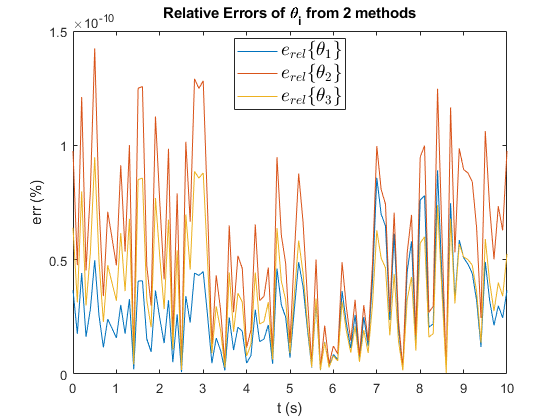

t = 0:step:T;

figure(1)
plot(t, delta(1,:), 'DisplayName', '$e_{rel}\{\theta_1\}$')
hold on
plot(t, delta(2,:), 'DisplayName', '$e_{rel}\{\theta_2\}$')
plot(t, delta(3,:), 'DisplayName', '$e_{rel}\{\theta_3\}$')
hold off
xlabel("t (s)");
ylabel("err (%)");
title("Relative Errors of \theta_i from 2 methods")
legend('Interpreter', 'latex', 'FontSize', 14, 'Location', 'best')

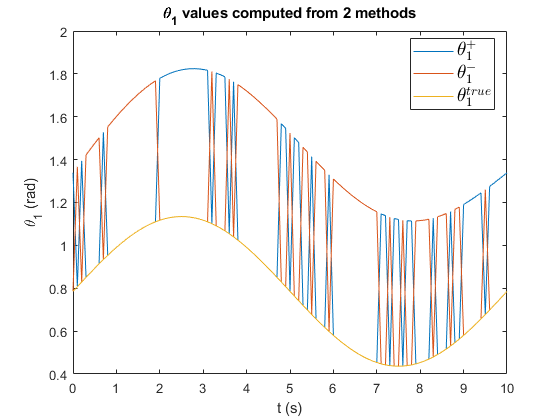


figure(2)
plot(t, t1(1,:), 'DisplayName', '$\theta_1^+$')
hold on
plot(t, t1(2,:), 'DisplayName', '$\theta_1^-$')
plot(t, theta(1,:), 'DisplayName', '$\theta_1^{true}$')
hold off
xlabel("t (s)");
ylabel("\theta_1 (rad)");
title("\theta_1 values computed from 2 methods")
legend('Interpreter', 'latex', 'FontSize', 14, 'Location', 'best')

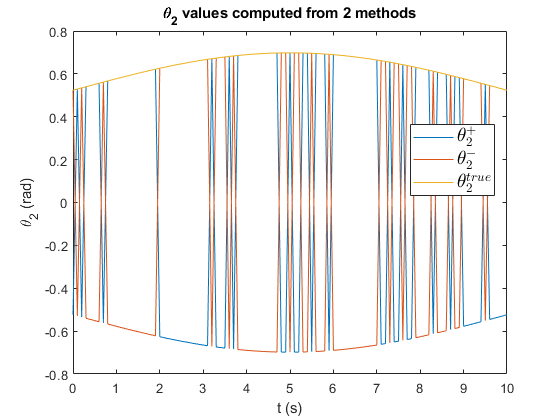


figure(3)
plot(t, t2(1,:),'DisplayName', '$\theta_2^+$' )
hold on
plot(t, t2(2,:), 'DisplayName', '$\theta_2^-$')
plot(t, theta(2,:), 'DisplayName', '$\theta_2^{true}$')
hold off
xlabel("t (s)");
ylabel("\theta_2 (rad)");
title("\theta_2 values computed from 2 methods")
legend('Interpreter', 'latex', 'FontSize', 14, 'Location', 'best')

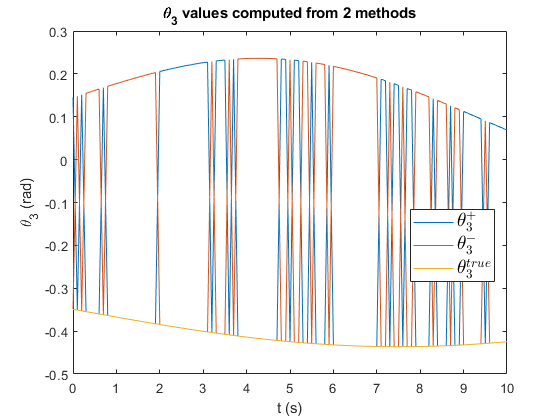


figure(4)
plot(t, t3(1,:), 'DisplayName', '$\theta_3^+$')
hold on
plot(t, t3(2,:), 'DisplayName', '$\theta_3^-$')
plot(t, theta(3,:), 'DisplayName', '$\theta_3^{true}$')
hold off
xlabel("t (s)");
ylabel("\theta_3 (rad)");
title("\theta_3 values computed from 2 methods")
legend('Interpreter', 'latex', 'FontSize', 14, 'Location', 'best')

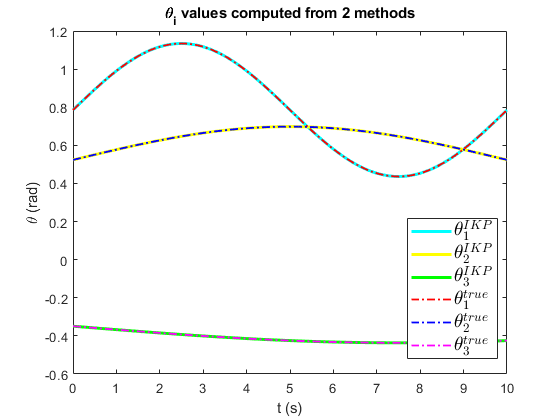


figure(5)
plot(t, th_IKP(1,:), 'cyan', 'DisplayName', '$\theta_1^{IKP}$', 'LineWidth', 2.2)
hold on
plot(t, th_IKP(2,:), 'yellow', 'DisplayName', '$\theta_2^{IKP}$', 'LineWidth', 2.2)
plot(t, th_IKP(3,:), 'green', 'DisplayName', '$\theta_3^{IKP}$', 'LineWidth', 2.2)
plot(t, theta(1,:), 'r-.', 'DisplayName', '$\theta_1^{true}$', 'LineWidth', 1.4)
plot(t, theta(2,:), 'b-.', 'DisplayName', '$\theta_2^{true}$', 'LineWidth', 1.4)
plot(t, theta(3,:), 'm-.', 'DisplayName', '$\theta_3^{true}$', 'LineWidth', 1.4)
hold off
xlabel("t (s)");
ylabel("\theta (rad)");
title("\theta_i values computed from 2 methods")
legend('Interpreter', 'latex', 'FontSize', 14, 'Location', 'best')

function [th1, th2, th3] = IKP(theta_1, theta_2, theta_3)
L_1 = 17;
L_2 = 19;
L_3 = 23;
phi = theta_1 + theta_2 + theta_3;
x = L_1*cos(theta_1) + L_2*cos(theta_1+theta_2) + L_3*cos(phi);
y = L_1*sin(theta_1) + L_2*sin(theta_1+theta_2) + L_3*sin(phi);
A = 2*L_1*(x - L_3*cos(phi));
B = 2*L_1*(y - L_3*sin(phi));
C = x^2 + y^2 + L_1^2 - L_2^2 + L_3^2 - 2*L_3*(x*cos(phi) + y*sin(phi));
syms th1
eq1 = vpa(A, 5)*cos(th1) + vpa(B, 5)*sin(th1) == vpa(C, 5);
s = solve(eq1, th1);
th1_1 = vpa(real(s(1)), 7)
th1_2 = vpa(real(s(2)), 7)

sin1 = (y-L_3*sin(phi)-L_1*sin(th1_1))/L_2;
cos1 = (x-L_3*cos(phi)-L_1*cos(th1_1))/L_2;
th2_1 = vpa(atan2(sin1, cos1) - th1_1, 7)

sin2 = (y-L_3*sin(phi)-L_1*sin(th1_2))/L_2;
cos2 = (x-L_3*cos(phi)-L_1*cos(th1_2))/L_2;
th2_2 = vpa(atan2(sin2, cos2) - th1_2, 7)

th3_1 = vpa(phi - th1_1 - th2_1, 7)
th3_2 = vpa(phi - th1_2 - th2_2, 7)

th1 = [th1_1, th1_2];
th2 = [th2_1, th2_2];
th3 = [th3_1, th3_2];
end